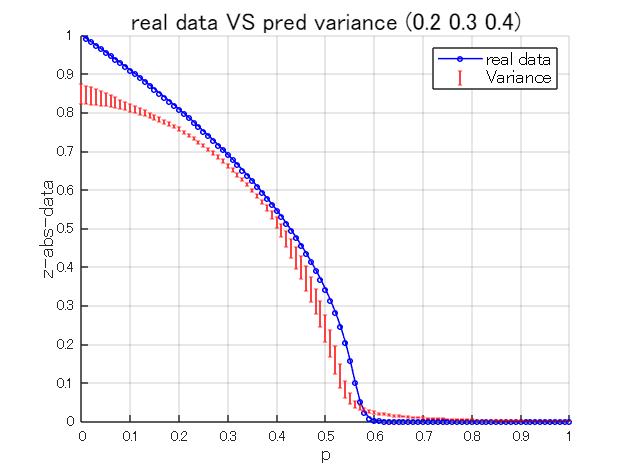

% ファイル名を指定
filename = 'resources/data(0.2,0.3,0.4).txt';
fileNameToUseDailyReport = 'plotFile/variance.pdf';

% データの読み取り
if isfile(filename)
    data = dlmread(filename, '\t'); % データを読み込む
    [n, cols] = size(data); % 行列サイズを取得
    
    % データの検証
    if cols ~= 101
        error('data.txt の列数が 101 ではありません。列数を確認してください。');
    end
else
    error(['ファイル ', filename, ' が存在しません。']);
end

% 横軸 p の定義
p = 0:0.01:1;

% 分散を計算（2行目からn行目まで）
variance = var(data(2:end, :), 1, 1); % 列方向に分散を計算

% グラフの作成
figure;
hold on;

% 1行目のプロット
plot(p, data(1, :), '-o', ... % 線と丸を同時に描画
    'MarkerFaceColor', 'none', ... % 丸の中を塗らない
    'MarkerEdgeColor', 'b', ... % 丸の縁の色
    'MarkerSize', 3, ... % 丸のサイズを小さくする
    'LineWidth', 1, ... % 線の太さ
    'Color', 'b', ... % 線の色
    'DisplayName', 'real data'); % 凡例で表示される名前を設定

% 縦棒（エラーバー）のプロット
errorbar(p, mean(data(2:end, :), 1), sqrt(variance), 'r', ...
    'LineStyle', 'none', ... % 縦線のみ
    'CapSize', 3, ... % 横棒をなくす
    'DisplayName', 'Variance');

% グラフの装飾
xlabel('p', 'FontSize', 14); % X軸ラベルの文字サイズを14に設定
ylabel('z-abs-data', 'FontSize', 14); % Y軸ラベルの文字サイズを14に設定
ylim([0 1]); % Y軸の範囲を設定
title('real data VS pred variance (0.2 0.3 0.4)', 'FontSize', 16); % タイトルの文字サイズを16に設定
legend('show', 'FontSize', 12); % 凡例の文字サイズを12に設定
grid on; % グリッドを表示
hold off;

% プロットをPDFに保存
exportgraphics(gcf, fileNameToUseDailyReport, 'Append', true); % 'Append'でPDFに追加
close(gcf); % 図を閉じる
toc; % 実行時間を測定

経過時間は 417.974643 秒です。
